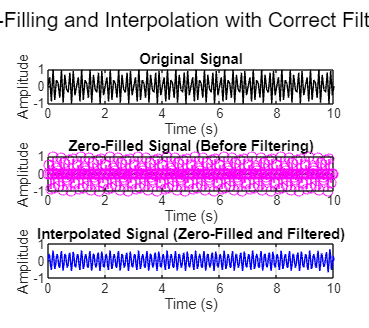

% Define original and target sample rates
freq_sam_min = 17;  % Hz Low
freq_sam_max = 24;  % Hz High

% Define signal parameters
delta = 7;  % Hz
sec = 10;  % seconds

% Create the original sine wave signal
r = 0:1/freq_sam_min:sec;  % Time vector
original_signal = sin(2*pi*delta*r);

% Zero filling (upsample by 4)
upsampling_factor = 2;  % Define a named constant
zero_filled_signal = zeros(1, length(original_signal) * upsampling_factor);
zero_filled_signal(1:upsampling_factor:end) = original_signal;  % Insert the original signal every 2nd sample

% Low-pass filtering (after zero filling)
filter_order = 10;  % Consider increasing the filter order for a sharper cutoff
cutoff_freq = freq_sam_min / 5;  % Nyquist frequency of the original signal

% Design a low-pass filter using the butterworth filter
[b, a] = butter(filter_order, cutoff_freq / (freq_sam_max / 4));  % fs_target / 6 is the Nyquist freq after upsampling

% Apply low-pass filtering (use filtfilt for zero-phase filtering)
interpolated_signal = filtfilt(b, a, zero_filled_signal);  % Zero-phase filtering to avoid delay

% Time vector for upsampled signal (adjust the length to match interpolated_signal)
t_upsampled = linspace(0, sec, length(interpolated_signal));  % Adjusted time vector

% Plot the results
figure;
subplot(3,1,1);
plot(r, original_signal, 'k-');
grid on;
title('Original Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2);
stem(linspace(0, sec, length(zero_filled_signal)), zero_filled_signal, 'm-');  % Adjusted stem plot
grid on;
title('Zero-Filled Signal (Before Filtering)');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,3);
plot(t_upsampled, interpolated_signal, 'b-');  % Adjusted time vector for the filtered signal
grid on;
title('Interpolated Signal (Zero-Filled and Filtered)');
xlabel('Time (s)');
ylabel('Amplitude');

% Adjust the figure layout
sgtitle('Zero-Filling and Interpolation with Correct Filtering');
set(gcf, 'Position', [120, 120, 900, 800]);